Read a hyperspectral data into the workspace. 

load("wavelengths.mat")
hcube = hypercube('CROP1_47.tiff',wavelength);

`Now we will use the ECOSTRESS signature library to classify different elements' spectrums`

fileroot = matlabshared.supportpkg.getSupportPackageRoot();
addpath(fullfile(fileroot,'toolbox','images','supportpackages','hyperspectral',...
    'hyperdata','ECOSTRESSSpectraFiles'));

filenames = ["water.seawater.none.liquid.tir.seafoam.jhu.becknic.spectrum.txt",...
    "vegetation.tree.eucalyptus.maculata.vswir.jpl087.jpl.asd.spectrum.txt",...
    "soil.utisol.hapludult.none.all.87p707.jhu.becknic.spectrum.txt",...
    "soil.mollisol.cryoboroll.none.all.85p4663.jhu.becknic.spectrum.txt",...    
    "manmade.concrete.pavingconcrete.solid.all.0092uuu_cnc.jhu.becknic.spectrum.txt"];
lib = readEcostressSig(filenames)

lib = 1×5 struct array with fields:
    Name
    Type
    Class
    SubClass
    ParticleSize
    Genus
    Species
    SampleNo
    Owner
    WavelengthRange
    Origin
    CollectionDate
    Description
    Measurement
    FirstColumn
    SecondColumn
    WavelengthUnit
    DataUnit
    FirstXValue
    LastXValue
    NumberOfXValues
    AdditionalInformation
    Wavelength
    Reflectance


classNames = [lib.Class];

Plot the pure spectral signatures read from the ECOSTRESS spectral library.

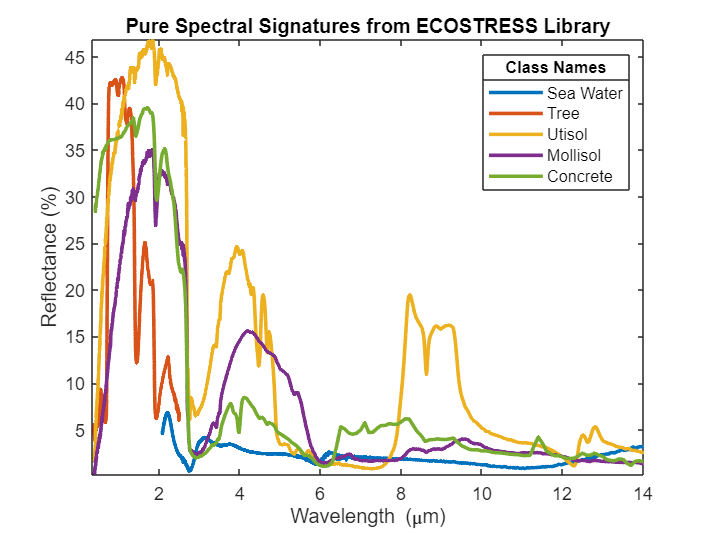

figure
hold on
for idx = 1:numel(lib)
    plot(lib(idx).Wavelength,lib(idx).Reflectance,'LineWidth',2)
end
axis tight
box on
title('Pure Spectral Signatures from ECOSTRESS Library')
xlabel('Wavelength (\mum)')
ylabel('Reflectance (%)')
legend(classNames,'Location','northeast')
title(legend,'Class Names')
hold off

The SAM spectralMatch compares the spectral signatures of the materials differentiated from the ECOSTRESS library to the spectral signatures of the points of the map

scoreMap = spectralMatch(lib,hcube);

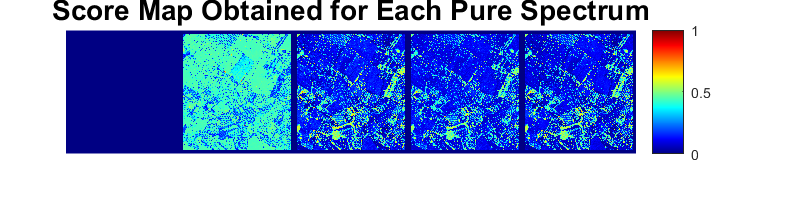

figure
montage(scoreMap,'Size',[1 numel(lib)],'BorderSize',10)
title('Score Map Obtained for Each Pure Spectrum','FontSize',14)
colormap(jet);
colorbar

Once this has been done, we can differentiate from the scoreMap the different elements classified

[~,classMap] = min(scoreMap,[],3);
classTable = table((min(classMap(:)):max(classMap(:)))',classNames(2:5)',...
             'VariableNames',{'Classification map value','Matching library signature'})

classTable = 4×2 table
    Classification map value    Matching library signature
    ________________________    __________________________

               2                        "Tree"            
               3                        "Utisol"          
               4                        "Mollisol"        
               5                        "Concrete"        


And now plot the differently categorized points from scores

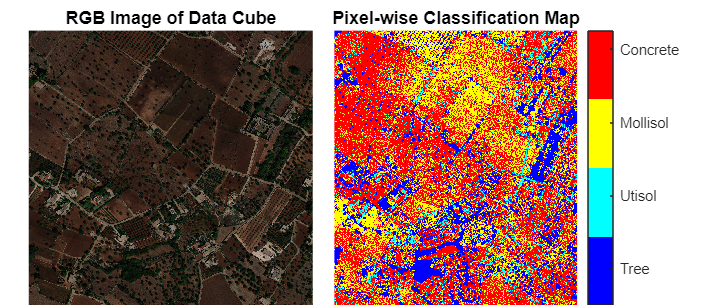

fig = figure('Position',[0 0 700 300]);
axes1 = axes('Parent',fig,'Position',[0.04 0 0.4 0.9]);
rgbImg= colorize(hcube,"Method","rgb","ContrastStretching",true);
imagesc(rgbImg,'Parent',axes1);
axis off
title('RGB Image of Data Cube')
axes2 = axes('Parent',fig,'Position',[0.47 0 0.45 0.9]);
imagesc(classMap,'Parent',axes2)
axis off
colormap(jet(numel(classNames(2:5))))
title('Pixel-wise Classification Map')
ticks = linspace(2.4,4.8,numel(classNames(2:5)));
colorbar('Ticks',ticks,'TickLabels',classNames(2:5))